# Plant

clear
% Aerodynamic damping during rapid flight maneuvers in the fruit fly Drosophila
% B. Cheng, S. N. Fry, Q. Huang, X. Deng
% Journal of Experimental Biology 2010 213: 602-612; doi: 10.1242/jeb.038778
Cu = 21e-12;
I = 4.971e-12;
G_plant = tf(Cu,[I 0]) %Torque to Velocity

G_plant =
 
    2.1e-11
  -----------
  4.971e-12 s
 
Continuous-time transfer function.



# Globals

t_final = 10;
delta_t = 0.005;
t = 0:delta_t:t_final;

# Signal 1: Chirp

scale = 50;
f_start = 0.1;
f_end = 2;
chirps = scale*chirp(t,f_start,t(end),f_end,'linear',-90);
figure
plot(t,chirps)

# Signal 2: SoS

peakaccel = 50;
f = [0.5 1 2.5]; %Hz
p = [pi/6 pi/2 pi/3]; %rad
A = peakaccel ./ (2*pi*f);%(50/length(f))*ones(1,length(f));%

%Make a higher resolution t vector for finding zero crossing
highdelta = 0.00001;
t_temp = 0:highdelta:t_final;

sostemp = zeros(1,length(t_temp));
for i = 1:size(t_temp,2)
    for j = 1:length(f)
        sostemp(i) = sostemp(i) + A(j)*sin(2*pi*f(j)*t_temp(i)+p(j));    
    end
end
[zeroind,zerodist] = zerocross(sostemp);

t_cross = t_temp(zeroind);

%Time shifted SoS for initial value close to zero
sos = zeros(1,length(t));
for i = 1:size(t,2)
    for j = 1:length(f)
        sos(i) = sos(i) + A(j)*sin(2*pi*f(j)*(t(i)+t_cross)+p(j));    
    end
end

sostemp = zeros(1,length(t_temp));
for i = 1:size(t_temp,2)
    for j = 1:length(f)
        sostemp(i) = sostemp(i) + A(j)*sin(2*pi*f(j)*t_temp(i)+p(j));    
    end
end
[zeroind,zerodist] = zerocross(sostemp);

t_cross = t_temp(zeroind);

%Time shifted SoS for initial value close to zero
sos = zeros(1,length(t));
for i = 1:size(t,2)
    for j = 1:length(f)
        sos(i) = sos(i) + A(j)*sin(2*pi*f(j)*(t(i)+t_cross)+p(j));    
    end
end

figure
plot(t,sos)

# Signal 3: Array of pure sine waves

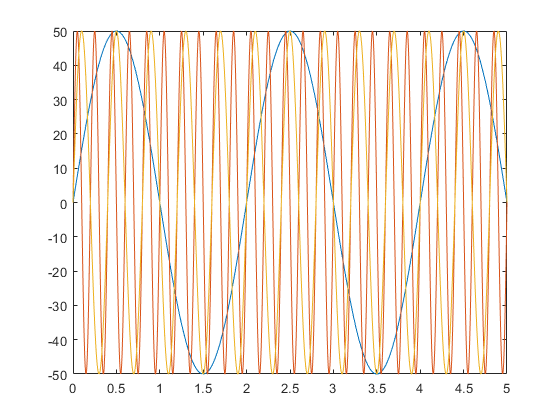

pureSinTime = 0:0.001:5;
sinfreqs = 0.5:0.5:5; %Hz
pureSin = zeros(length(sinfreqs),length(pureSinTime));
for i = 1:length(sinfreqs)
    for j = 1:length(pureSinTime)
        pureSin(i,j) = scale*sin(2*pi*sinfreqs(i)*pureSinTime(j));
    end
end

plot(pureSinTime,pureSin(1,:),pureSinTime,pureSin(end,:),pureSinTime,pureSin(round(end/2),:))

# Sweeps

Kp = .5:.5:15;
Ki = .5:.5:15;
td = 0.04:0.04:0.04;
numinners = size(Kp,2)*size(Ki,2);

chirperror = zeros(numinners,3,size(td,2));
soserror = zeros(numinners,3,size(td,2));
strisetime = zeros(numinners,3,size(td,2));
stsettlingtime = zeros(numinners,3,size(td,2));
stovershoot = zeros(numinners,3,size(td,2));

for i = 1:size(td,2)
    tic
    iter = 1;
    for j = 1:size(Kp,2)
        tic
        for k = 1:size(Ki,2)
            %Controller TF
            C_tf = tf([Kp(j) Ki(k)],[1 0]);
            
            %Delay (Pade approximation)
            [nump,denp]=pade(td(i),3);
            d_tf = tf(nump,denp);
            
            %Closed Loop Transfer Function
            num = C_tf*G_plant*d_tf;
            oltf = minreal(num);
            den = (1 + oltf);
            cl_tf = num/den;
            
            %Stability
            s = isstablemod(cl_tf);
            if s == 1
                stepopt=stepDataOptions('StepAmplitude',scale);
                %step
                st = stepinfo(step(cl_tf,stepopt));
                
                %Performance Metrics
                if st.RiseTime < 0
                   strisetime(iter,:,i) = [Kp(j) Ki(k) 0];
                else
                    strisetime(iter,:,i) = [Kp(j) Ki(k) st.RiseTime];
                end
                
                if st.SettlingTime < 0
                    stsettlingtime(iter,:,i) = [Kp(j) Ki(k) 0]; 
                else
                    stsettlingtime(iter,:,i) = [Kp(j) Ki(k) st.SettlingTime];
                end

                if st.Overshoot < 0
                    stovershoot(iter,:,i) = [Kp(j) Ki(k) 0]; 
                else
                    stovershoot(iter,:,i) = [Kp(j) Ki(k) st.Overshoot];
                end

                
                %lsim
                chirpsim = lsim(cl_tf,chirps,t);
                sossim = lsim(cl_tf,sos,t);
                
                chirpsum = sum(abs(chirps-chirpsim'));              
                sossum = sum(abs(sos-sossim'));

                %Errors
                chirperror(iter,:,i) = [Kp(j) Ki(k) chirpsum];
                soserror(iter,:,i) = [Kp(j) Ki(k) sossum];
                iter = iter + 1;
                
            else

            end
            
        end
        toc
    end
    toc
end
filename1 = strcat('ch','_',num2str(scale),'_',num2str(f_start),'_',num2str(f_end),'_');
filename2 = strcat('ssf','_',num2str(f(1)),'_',num2str(f(2)),'_',num2str(f(3)),'_');
filename3 = strcat('ssp','_',num2str(p(1)),'_',num2str(p(2)),'_',num2str(p(3)),'_');
filename4 = strcat('kp','_',num2str(Kp(1)),'_',num2str(Kp(2)-Kp(1)),'_',num2str(Kp(end)),'_');
filename5 = strcat('ki','_',num2str(Ki(1)),'_',num2str(Ki(2)-Ki(1)),'_',num2str(Ki(end)),'_');
filename6 = strcat('td','_',num2str(td(1)),'_',num2str(td(1)),'_',num2str(td(end)));
filename = strcat(filename1,filename2,filename3,filename4,filename5,filename6,'.mat')
save(filename,'chirperror','soserror','strisetime','stsettlingtime','stovershoot','Ki','Kp','td','chirps','sos','scale')

# Sweep Plots

subn = 1;
subp = 1;
figure
for i =  1:size(td,2)
    chirperrort = zerostrip(chirperror(:,:,i));
    subplot(subn,subp,i)
    sf = fit([chirperrort(:,1),chirperrort(:,2)],chirperrort(:,3),'cubicinterp');
    plot(sf)
    xlabel('K_P')
    ylabel('K_I')
    zlabel('SSE')
    title(['t_d = ', num2str(td(i),2)])
    xlim([Kp(1) Kp(end)])
    ylim([Ki(1) Ki(end)])
end
sgtitle('Sum-Squared Error Performance for Chirp input with increasing delay')

figure
for i =  1:size(td,2)
    soserrort = zerostrip(soserror(:,:,i));
    subplot(subn,subp,i)
    sf = fit([soserrort(:,1),soserrort(:,2)],soserrort(:,3),'cubicinterp');
    plot(sf)
    xlabel('K_P')
    ylabel('K_I')
    zlabel('SSE')
    title(['t_d = ', num2str(td(i),2)])
    xlim([Kp(1) Kp(end)])
    ylim([Ki(1) Ki(end)])
end
sgtitle('Sum-Squared Error Performance for SoS input with increasing delay')

figure
for i =  1:size(td,2)
    strisetimet = zerostrip(strisetime(:,:,i));
    subplot(subn,subp,i)
    sf = fit([strisetimet(:,1),strisetimet(:,2)],strisetimet(:,3),'cubicinterp');
    plot(sf)
    xlabel('K_P')
    ylabel('K_I')
    zlabel('Rise Time')
    title(['t_d = ', num2str(td(i),2)])
    xlim([Kp(1) Kp(end)])
    ylim([Ki(1) Ki(end)])
end
sgtitle('Rise time of step response with increasing delay')

figure
for i =  1:size(td,2)
    stsettlingtimet = zerostrip(stsettlingtime(:,:,i));
    subplot(subn,subp,i)
    sf = fit([stsettlingtimet(:,1),stsettlingtimet(:,2)],stsettlingtimet(:,3),'cubicinterp');
    plot(sf)
    xlabel('K_P')
    ylabel('K_I')
    zlabel('Settling Time')
    title(['t_d = ', num2str(td(i),2)])
    xlim([Kp(1) Kp(end)])
    ylim([Ki(1) Ki(end)])
end
sgtitle('Settling time of step response with increasing delay')

figure
for i =  1:size(td,2)
    stovershoott = zerostrip(stovershoot(:,:,i));
    subplot(subn,subp,i)
    sf = fit([stovershoott(:,1),stovershoott(:,2)],stovershoott(:,3),'cubicinterp');
    plot(sf)
    xlabel('K_P')
    ylabel('K_I')
    zlabel('Overshoot')
    title(['t_d = ', num2str(td(i),2)])
    xlim([Kp(1) Kp(end)])
    ylim([Ki(1) Ki(end)])
end
sgtitle('Overshoot of step response with increasing delay')

# 0.04 Delay (standard for fly)

ind04 = 1;
figure
chirperror04 = zerostrip(chirperror(:,:,ind04));
sfchirp = fit([chirperror04(:,1),chirperror04(:,2)],normalize(chirperror04(:,3),'range'),'cubicinterp');
plot(sfchirp)
hold on

soserror04 = zerostrip(soserror(:,:,ind04));
sfsos = fit([soserror04(:,1),soserror04(:,2)],normalize(soserror04(:,3),'range'),'cubicinterp');
plot(sfsos)

risetime04 = zerostrip(strisetime(:,:,ind04));
sfrisetime = fit([risetime04(:,1),risetime04(:,2)],normalize(risetime04(:,3),'range'),'cubicinterp');
plot(sfrisetime)

settlingtime04 = zerostrip(stsettlingtime(:,:,ind04));
sfsettlingtime = fit([settlingtime04(:,1),settlingtime04(:,2)],normalize(settlingtime04(:,3),'range'),'cubicinterp');
plot(sfsettlingtime)

overshoot04 = zerostrip(stovershoot(:,:,ind04));
sfovershoot = fit([overshoot04(:,1),overshoot04(:,2)],normalize(overshoot04(:,3),'range'),'cubicinterp');
plot(sfovershoot)

xlabel('K_P')
ylabel('K_I')
zlabel('SSE')
title('t_d = 0.04')
%xlim([Kp(1) Kp(end)])
%ylim([Ki(1) Ki(end)])

# Weighting and Composite Surface

weights = [0 1 0 0 0]'; %Chirp SSE, SoS SSE, Rise, Settling, Overshoot
normchirpses = normalize(chirperror04(:,3),'range');
normsosses = normalize(soserror04(:,3),'range');
normrisetime = normalize(risetime04(:,3),'range');
normsettlingtime = normalize(settlingtime04(:,3),'range');
normovershoot = normalize(overshoot04(:,3),'range');
norms = [normchirpses normsosses normrisetime normsettlingtime normovershoot];
composite = norms*weights;

sfcomposite = fit([overshoot04(:,1),overshoot04(:,2)],composite,'cubicinterp');

figure
plot(sfcomposite)
xlabel('K_P')
ylabel('K_I')
zlabel('Composite score')
title('t_d = 0.04')

[minimum,index] = min(composite)
minKp = overshoot04(index,1)
minKi = overshoot04(index,2)

# Single Point

%PI controller
Kp = 6;
Ki = .05;

C_tf = tf([Kp Ki],[1 0])

%Delay (Pade approximation)
sym s;
td =.04;
s = tf('s');
[nump,denp]=pade(td,3);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = C_tf*G_plant*d_tf;
oltf = minreal(num);
den = (1 + oltf);
cl_tf = num/den;
figure
pzmap(cl_tf);
figure
step(cl_tf);
figure
margin(cl_tf)
figure1=figure('Position', [100, 100, 1024, 1200]);
subplot(2,1,1)
h = nyquistplot(oltf);
p = getoptions(h);
p.XLim = {[-3, 0.5]};
p.YLim = {[-1.5, 1.5]};
setoptions(h,p);
subplot(2,1,2)
pzmap(cl_tf);

# Simulation and Plots

chirpsim = lsim(cl_tf,chirps,t);
sossim = lsim(cl_tf,sos,t);

figure
plot(t,chirps,t,chirpsim)
figure
plot(t,sos,t,sossim)

# Error Calculations

chirperrorsingle = sum((chirps-chirpsim').^2)
soserrorsingle = sum((sos-sossim').^2)


# Tracking Error, pure sin (FRF)

## Kp, Freq sweep

Kp = 0.5:0.5:10;
Ki = 10;

%Delay (Pade approximation)
td =.04;
[nump,denp]=pade(td,5);
d_tf = tf(nump,denp);

%FFT Params
Fs = 1/(pureSinTime(2)-pureSinTime(1));
N = 10000;

%Data Array
tracksweepP = repmat(struct('gain',-1,'phase',-1),length(Kp),length(sinfreqs));

for i = 1:length(Kp)
    C_tf = tf([Kp(i) Ki],[1 0]);

    %Closed Loop Transfer Function
    num = C_tf*G_plant*d_tf;
    oltf = minreal(num);
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Stability check
    s = isstablemod(cl_tf);
    if s == 1
       for j = 1:length(sinfreqs)
            %Simulate
            sinin = pureSin(j,:);
            sinout = lsim(cl_tf,sinin,pureSinTime);
            
            %FRF Analysis
            ffin = fft(sinin,N);
            ffout = fft(sinout,N);
            ffindex = 1 + sinfreqs(j)/(Fs/N);
            magratio = abs(ffout(ffindex))/abs(ffin(ffindex));
            phaseshift = angle(ffout(ffindex)) - angle(ffin(ffindex));
            
            tracksweepP(i,j).gain = magratio;
            tracksweepP(i,j).phase = phaseshift;
        end 
    end
end

figure
linecolors = [{'k'} {'b'} {'r'} {'g'} {'m'} {'c'}];
selectedFreqIndex = [1 3 5 7 9 10];%1:1:length(sinfreqs);

selectedFreqIndex =      1     3     5     7     9    10


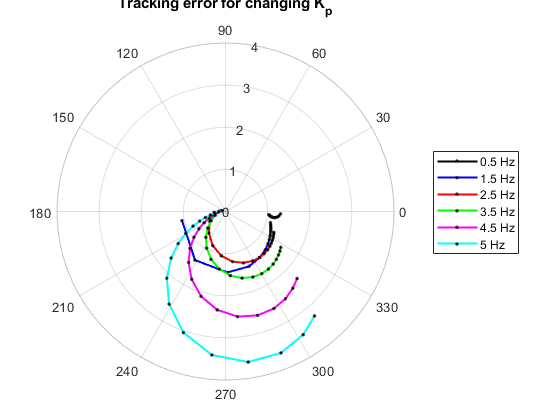

for i = 1:length(selectedFreqIndex)
    %Repack data
    tmags = zeros(1,length(Kp));
    tphases = zeros(1,length(Kp));
    iter = 1;
    for j = 1:length(Kp)
        if tracksweepP(j,selectedFreqIndex(i)).gain ~= -1
            tmags(iter) = tracksweepP(j,selectedFreqIndex(i)).gain;
            tphases(iter) = tracksweepP(j,selectedFreqIndex(i)).phase;
            if tphases(iter) < 0
                %Not necessary, but makes it easier to see trends in data
                tphases(iter) = tphases(iter) + 2*pi;
            end
            iter = iter+1;
        end
    end
    tmags = zerostrip1d(tmags);
    tphases = zerostrip1d(tphases);
    polarplot(tphases,tmags,'.-','MarkerEdgeColor','k','MarkerSize',6,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    hold on
    lgd{i} = strcat(num2str(sinfreqs(selectedFreqIndex(i))),' Hz');
end
legend(lgd)
rlim([0 4])
title('Tracking error for changing K_p')

## Ki, Freq sweep

Kp = 5;
Ki = 5:5:100;

%Delay (Pade approximation)
td =.04;
[nump,denp]=pade(td,5);
d_tf = tf(nump,denp);

%FFT Params
Fs = 1/(pureSinTime(2)-pureSinTime(1));
N = 10000;

%Data Array
tracksweepP = repmat(struct('gain',-1,'phase',-1),length(Ki),length(sinfreqs));

for i = 1:length(Ki)
    C_tf = tf([Kp Ki(i)],[1 0]);

    %Closed Loop Transfer Function
    num = C_tf*G_plant*d_tf;
    oltf = minreal(num);
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Stability check
    s = isstablemod(cl_tf);
    if s == 1
       for j = 1:length(sinfreqs)
            %Simulate
            sinin = pureSin(j,:);
            sinout = lsim(cl_tf,sinin,pureSinTime);
            
            %FRF Analysis
            ffin = fft(sinin,N);
            ffout = fft(sinout,N);
            ffindex = 1 + sinfreqs(j)/(Fs/N);
            magratio = abs(ffout(ffindex))/abs(ffin(ffindex));
            phaseshift = angle(ffout(ffindex)) - angle(ffin(ffindex));
            
            tracksweepP(i,j).gain = magratio;
            tracksweepP(i,j).phase = phaseshift;
        end 
    end
end

figure
linecolors = [{'k'} {'b'} {'r'} {'g'} {'m'} {'c'}];
selectedFreqIndex = [1 3 5 7 9 10];%1:1:length(sinfreqs);

selectedFreqIndex =      1     3     5     7     9    10


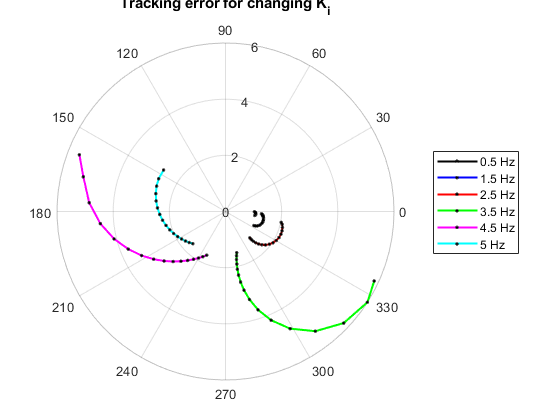

for i = 1:length(selectedFreqIndex)
    %Repack data
    tmags = zeros(1,length(Ki));
    tphases = zeros(1,length(Ki));
    iter = 1;
    for j = 1:length(Ki)
        if tracksweepP(j,selectedFreqIndex(i)).gain ~= -1
            tmags(iter) = tracksweepP(j,selectedFreqIndex(i)).gain;
            tphases(iter) = tracksweepP(j,selectedFreqIndex(i)).phase;
            if tphases(iter) < 0
                %Not necessary, but makes it easier to see trends in data
                tphases(iter) = tphases(iter) + 2*pi;
            end
            iter = iter+1;
        end
    end
    tmags = zerostrip1d(tmags);
    tphases = zerostrip1d(tphases);
    polarplot(tphases,tmags,'.-','MarkerEdgeColor','k','MarkerSize',6,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    hold on
    lgd{i} = strcat(num2str(sinfreqs(selectedFreqIndex(i))),' Hz');
end
legend(lgd)
%rlim([0 4])
title('Tracking error for changing K_i')

## Delay sweep

Kp = 5;
Ki = 10;
C_tf = tf([Kp Ki],[1 0]);
td =0.01:0.01:0.1;


%FFT Params
Fs = 1/(pureSinTime(2)-pureSinTime(1));
N = 10000;

%Data Array
tracksweepP = repmat(struct('gain',-1,'phase',-1),length(td),length(sinfreqs));

for i = 1:length(td)
    %Delay (Pade approximation)
    [nump,denp]=pade(td(i),5);
    d_tf = tf(nump,denp);
    
    %Closed Loop Transfer Function
    num = C_tf*G_plant*d_tf;
    oltf = minreal(num);
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Stability check
    s = isstablemod(cl_tf);
    if s == 1
       for j = 1:length(sinfreqs)
            %Simulate
            sinin = pureSin(j,:);
            sinout = lsim(cl_tf,sinin,pureSinTime);
            
            %FRF Analysis
            ffin = fft(sinin,N);
            ffout = fft(sinout,N);
            ffindex = 1 + sinfreqs(j)/(Fs/N);
            magratio = abs(ffout(ffindex))/abs(ffin(ffindex));
            phaseshift = angle(ffout(ffindex)) - angle(ffin(ffindex));
            
            tracksweepP(i,j).gain = magratio;
            tracksweepP(i,j).phase = phaseshift;
        end 
    end
end

figure
linecolors = [{'k'} {'b'} {'r'} {'g'} {'m'} {'c'}];
selectedFreqIndex = [1 3 5 7 9 10];%1:1:length(sinfreqs);

selectedFreqIndex =      1     3     5     7     9    10


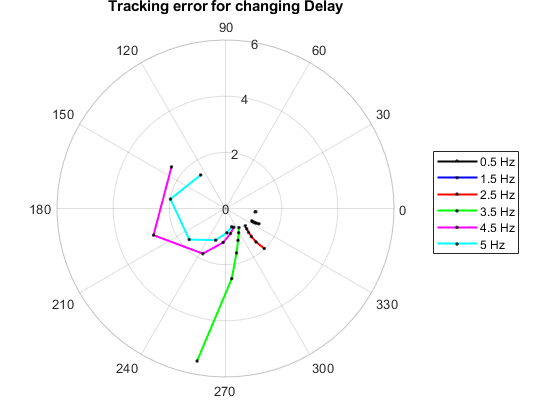

for i = 1:length(selectedFreqIndex)
    %Repack data
    tmags = zeros(1,length(td));
    tphases = zeros(1,length(td));
    iter = 1;
    for j = 1:length(td)
        if tracksweepP(j,selectedFreqIndex(i)).gain ~= -1
            tmags(iter) = tracksweepP(j,selectedFreqIndex(i)).gain;
            tphases(iter) = tracksweepP(j,selectedFreqIndex(i)).phase;
            if tphases(iter) < 0
                %Not necessary, but makes it easier to see trends in data
                tphases(iter) = tphases(iter) + 2*pi;
            end
            iter = iter+1;
        end
    end
    tmags = zerostrip1d(tmags);
    tphases = zerostrip1d(tphases);
    polarplot(tphases,tmags,'.-','MarkerEdgeColor','k','MarkerSize',6,'Color',cell2mat(linecolors(i)),'LineWidth',1.5)
    hold on
    lgd{i} = strcat(num2str(sinfreqs(selectedFreqIndex(i))),' Hz');
end
legend(lgd)
%rlim([0 4])
title('Tracking error for changing Delay')

# Sum-Abs Error as a function of frequency

pureSinTime = 0:0.001:5;
sinfreqs = 0.5:0.5:5; %Hz
pureSin = zeros(length(sinfreqs),length(pureSinTime));
for i = 1:length(sinfreqs)
    for j = 1:length(pureSinTime)
        pureSin(i,j) = scale*sin(2*pi*sinfreqs(i)*pureSinTime(j));
    end
end

plot(pureSinTime,pureSin(1,:),pureSinTime,pureSin(end,:),pureSinTime,pureSin(round(end/2),:))